# Actividad 7.1 (Waypoints)

Bruno Manuel Zamora Garcia A01798275

**1. Resumen**

Este reporte unifica seis simulaciones de seguimiento de waypoints usando Pure Pursuit sobre un robot diferencial. Primero presentamos tres trayectorias fijas  y luego tres trayectorias con forma (perro,flor y cereza). En cada caso, Pure Pursuit calcula en tiempo real las velocidades lineal y angular y Euler explícito actualiza la pose del robot.

**2. Parámetros de simulacion**

**3.Parametros de Pure Pursuit**

**Parte 1**

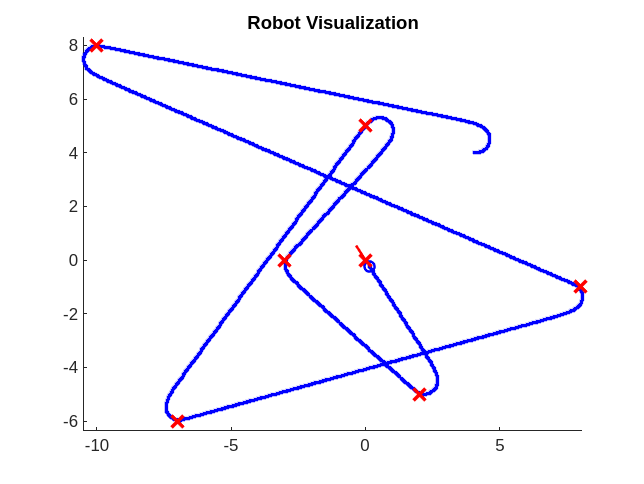

clear; close all; clc


% Defino el robot diferencial
R  = 0.05;           % Radio de rueda [m]
L  = 0.18;           % Separación entre ruedas [m]
dd = DifferentialDrive(R, L);

% Parámetros de simulación comunes
sampleTime = 0.1;              
tVec       = 0:sampleTime:160; 


% ---- Trayectoria 1
initPose    = [4; 4; 0];           
pose         = zeros(3, numel(tVec));
pose(:,1)    = initPose;            
waypoints    = [
   -10,  8;
     8, -1;
    -7, -6;
     0,  5;
    -3,   0;
     2, -5;
     0,   0
];

figure(1); clf
viz1 = Visualizer2D;              % Visualizo robot y waypoints
viz1.hasWaypoints = true;

controller = controllerPurePursuit;    % Configuro Pure Pursuit
controller.LookaheadDistance    = 1.0;
controller.DesiredLinearVelocity= 0.6;
controller.MaxAngularVelocity   = 1.2;

r = rateControl(1/sampleTime);
currentIdx = 1;
goalRadius = 0.3;

for idx = 2:numel(tVec)
    if currentIdx > size(waypoints,1), break; end
    
    % Actualizo waypoint objetivo
    controller.Waypoints = [pose(1:2,idx-1)' ; waypoints(currentIdx,:)];
    [vRef,wRef]         = controller(pose(:,idx-1));
    
    % Cinemática diferencial
    [wL,wR]             = inverseKinematics(dd, vRef, wRef);
    [v, w]              = forwardKinematics(dd, wL, wR);
    vel                 = bodyToWorld([v;0;w], pose(:,idx-1));
    
    % Euler explícito
    pose(:,idx) = pose(:,idx-1) + vel * sampleTime;
    
    % Cambio de waypoint
    if norm(pose(1:2,idx) - waypoints(currentIdx,:)') < goalRadius
        currentIdx = currentIdx + 1;
    end
    
    viz1(pose(:,idx), waypoints);  % Dibujo
    waitfor(r);
end

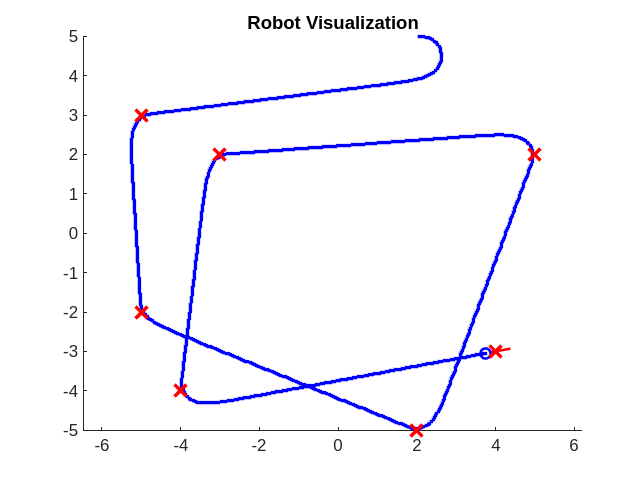


% ---- Trayectoria 2
initPose    = [2; 5; 0];
pose         = zeros(3, numel(tVec));
pose(:,1)    = initPose;            
waypoints    = [
    -5,  3;
    -5, -2;
     2, -5;
     5,  2;
    -3,  2;
    -4, -4;
     4, -3
];

figure(2); clf
viz2 = Visualizer2D; viz2.hasWaypoints = true;
controller.Waypoints = waypoints;
currentIdx = 1;

for idx = 2:numel(tVec)
    if currentIdx > size(waypoints,1), break; end
    
    controller.Waypoints = [pose(1:2,idx-1)' ; waypoints(currentIdx,:)];
    [vRef,wRef]         = controller(pose(:,idx-1));
    [wL,wR]             = inverseKinematics(dd, vRef, wRef);
    [v, w]              = forwardKinematics(dd, wL, wR);
    
    vel                 = bodyToWorld([v;0;w], pose(:,idx-1));
    pose(:,idx)         = pose(:,idx-1) + vel * sampleTime;
    
    if norm(pose(1:2,idx) - waypoints(currentIdx,:)') < goalRadius
        currentIdx = currentIdx + 1;
    end
    
    viz2(pose(:,idx), waypoints);
    waitfor(r);
end

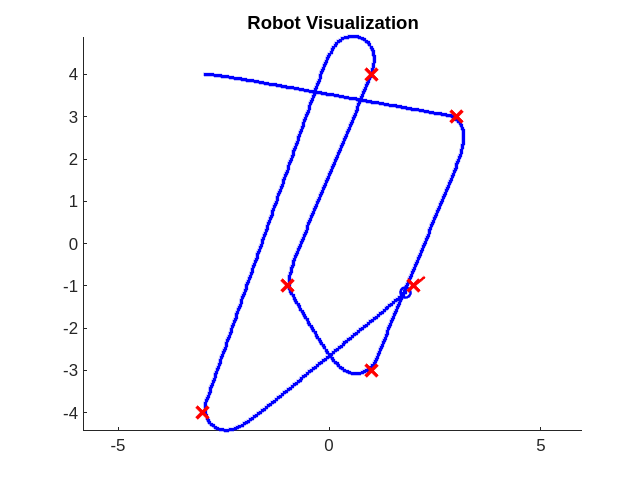


% ---- Trayectoria 3
initPose    = [-3; 4; 0];
pose         = zeros(3, numel(tVec));
pose(:,1)    = initPose;            
waypoints    = [
     3,  3;
     1, -3;
    -1, -1;
     1,  4;
    -3, -4;
     2, -1
];

figure(3); clf
viz3 = Visualizer2D; viz3.hasWaypoints = true;
controller.Waypoints = waypoints;
currentIdx = 1;

for idx = 2:numel(tVec)
    if currentIdx > size(waypoints,1), break; end
    
    controller.Waypoints = [pose(1:2,idx-1)' ; waypoints(currentIdx,:)];
    [vRef,wRef]         = controller(pose(:,idx-1));
    [wL,wR]             = inverseKinematics(dd, vRef, wRef);
    [v, w]              = forwardKinematics(dd, wL, wR);
    
    vel                 = bodyToWorld([v;0;w], pose(:,idx-1));
    pose(:,idx)         = pose(:,idx-1) + vel * sampleTime;
    
    if norm(pose(1:2,idx) - waypoints(currentIdx,:)') < goalRadius
        currentIdx = currentIdx + 1;
    end
    
    viz3(pose(:,idx), waypoints);
    waitfor(r);
end

**Parte 2**

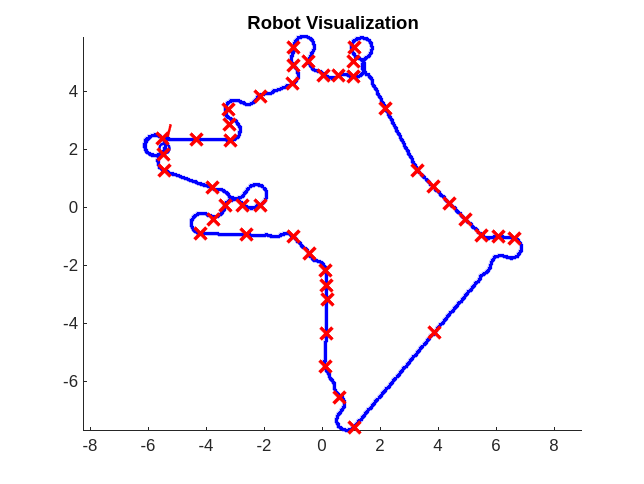


% ---- Perro
R1  = 0.1; L1 = 0.5;              
dd1 = DifferentialDrive(R1,L1);

sampleTime1 = 0.08;              
tVec1       = 0:sampleTime1:82; 

initPose1    = [-5.49; 2.36; 0];
pose1        = zeros(3, numel(tVec1));
pose1(:,1)   = initPose1;

waypoints1 = [
   -5.49,  2.36;  -4.33,  2.34;  -3.17,  2.32;
   -3.20,  2.84;  -3.23,  3.36;  -2.12,  3.81;
   -1.01,  4.26;  -1.00,  4.89;  -0.99,  5.52;
   -0.47,  5.04;   0.05,  4.56;   0.56,  4.54;
    1.07,  4.52;   1.09,  5.02;   1.11,  5.52;
    2.20,  3.40;   3.29,  1.28;   3.84,  0.71;
    4.39,  0.14;   4.95, -0.41;   5.51, -0.96;
    6.07, -1.01;   6.63, -1.06;   3.87, -4.32;
    1.11, -7.58;   0.61, -6.54;   0.11, -5.50;
    0.14, -4.34;   0.17, -3.18;   0.15, -2.68;
    0.13, -2.18;  -0.44, -1.59;  -1.00, -1.00;
   -2.60, -0.95;  -4.19, -0.90;  -3.76, -0.42;
   -3.33,  0.06;  -2.73,  0.07;  -2.13,  0.08;
   -3.79,  0.67;  -5.45,  1.26;  -5.47,  1.81;
   -5.49,  2.36
];

figure(4); clf
viz4 = Visualizer2D; viz4.hasWaypoints = true;

controller1 = controllerPurePursuit;
controller1.Waypoints             = waypoints1;
controller1.LookaheadDistance     = 0.09;
controller1.DesiredLinearVelocity = 0.75;
controller1.MaxAngularVelocity    = 2.13;

r1 = rateControl(1/sampleTime1);

for k = 2:numel(tVec1)
    [vRef,wRef] = controller1(pose1(:,k-1));
    [wL,wR]     = inverseKinematics(dd1, vRef, wRef);
    [v, w]      = forwardKinematics(dd1, wL, wR);
    vel         = bodyToWorld([v;0;w], pose1(:,k-1));
    pose1(:,k)  = pose1(:,k-1) + vel * sampleTime1;
    viz4(pose1(:,k), waypoints1);
    waitfor(r1);
end

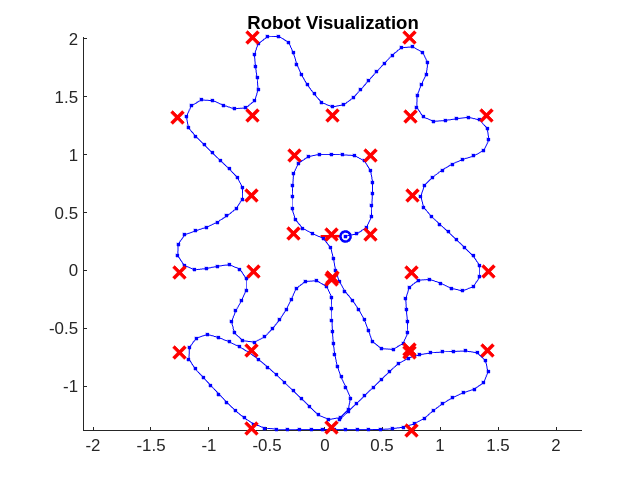


% ---- Flor  ----
R2  = 0.1; L2 = 0.5;              
dd2 = DifferentialDrive(R2,L2);

sampleTime2 = 0.2;              
tVec2       = 0:sampleTime2:45; 

initPose2    = [0.06; -1.36; pi/4];
pose2        = zeros(3, numel(tVec2));
pose2(:,1)   = initPose2;

waypoints2 = [
    0.06, -1.36;  0.73, -0.71;  1.41, -0.69;
    0.75, -1.38; -0.63, -1.37; -1.25, -0.71;
   -0.63, -0.69;  0.06, -1.36;  0.06, -0.08;
   -0.63, -0.69; -0.61, -0.01; -1.25, -0.02;
   -0.63,  0.65; -1.27,  1.32; -0.62,  1.34;
   -0.62,  2.01;  0.07,  1.34;  0.73,  2.01;
    0.74,  1.33;  1.40,  1.34;  0.76,  0.65;
    1.42, -0.01;  0.75, -0.02;  0.73, -0.68;
    0.07, -0.06;  0.06,  0.31; -0.27,  0.32;
   -0.26,  0.99;  0.40,  0.99;  0.40,  0.31;
    0.06,  0.31
];

figure(5); clf
viz5 = Visualizer2D; viz5.hasWaypoints = true;

controller2 = controllerPurePursuit;
controller2.Waypoints              = waypoints2;
controller2.LookaheadDistance      = 0.35;
controller2.DesiredLinearVelocity  = 0.5;
controller2.MaxAngularVelocity     = 3;

r2 = rateControl(1/sampleTime2);

for k = 2:numel(tVec2)
    [vRef,wRef] = controller2(pose2(:,k-1));
    [wL,wR]     = inverseKinematics(dd2, vRef, wRef);
    [v, w]      = forwardKinematics(dd2, wL, wR);
    vel         = bodyToWorld([v;0;w], pose2(:,k-1));
    pose2(:,k)  = pose2(:,k-1) + vel * sampleTime2;
    viz5(pose2(:,k), waypoints2);
    waitfor(r2);
end

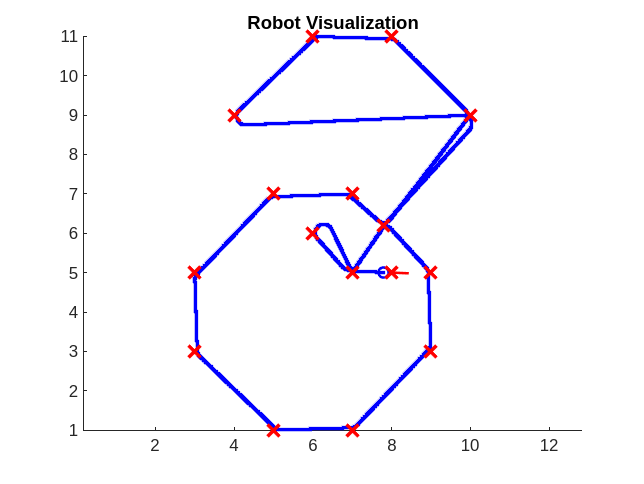


% ---- Cereza ----
R3  = 0.05; L3 = 0.18;              
dd3 = DifferentialDrive(R3,L3);

sampleTime3 = 0.04;              
tVec3       = 0:sampleTime3:300; 

initPose3    = [7.8; 6.2; 0];
pose3        = zeros(3, numel(tVec3));
pose3(:,1)   = initPose3;

waypoints3 = [
    9,5;  9,3;  7,1;  5,1;  3,3;  3,5;  5,7;
    7,7; 7.8,6.2; 10,9; 8,11; 6,11; 4,9; 10,9;
   7.8,6.2; 7,5; 6,6; 7,5; 8,5
];

figure(6); clf
viz6 = Visualizer2D; viz6.hasWaypoints = true;

controller3 = controllerPurePursuit;
controller3.LookaheadDistance     = 0.2;
controller3.DesiredLinearVelocity = 0.35;
controller3.MaxAngularVelocity    = 1.6;

r3 = rateControl(1/sampleTime3);
currentIdx3 = 1;
goalRadius3 = 0.2;

for k = 2:numel(tVec3)
    if currentIdx3 > size(waypoints3,1), break; end
    
    controller3.Waypoints = [pose3(1:2,k-1)' ; waypoints3(currentIdx3,:)];
    [vRef,wRef]          = controller3(pose3(:,k-1));
    [wL,wR]              = inverseKinematics(dd3, vRef, wRef);
    [v, w]               = forwardKinematics(dd3, wL, wR);
    vel                  = bodyToWorld([v;0;w], pose3(:,k-1));
    pose3(:,k)           = pose3(:,k-1) + vel * sampleTime3;
    
    if norm(pose3(1:2,k) - waypoints3(currentIdx3,:)') < goalRadius3
        currentIdx3 = currentIdx3 + 1;
    end
    
    viz6(pose3(:,k), waypoints3);
    waitfor(r3);
end